clear all
%Lectura matriu de digits
N=1000;
[images, labels] =readMNIST( ...
    'train-images-idx3-ubyte\train-images.idx3-ubyte', ...
    'train-labels-idx1-ubyte\train-labels.idx1-ubyte',N,30000);

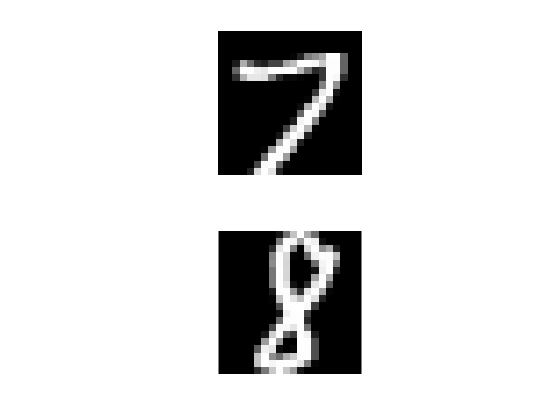

Nft = 2916;
vartypes = strings([1,Nft+1]);
vartypes{Nft+1} = 'string';
vartypes(1:Nft) = 'double';
T = table('Size',[N Nft+1],'VariableTypes',vartypes);



for i = 1:N
    im=images(:,:,i); 
    imshow(im)
%     [sumRow,sumCol,distRowLeft,distRowRight,distColUp,distColDown,diffRowLeft,diffRowRight,diffColUp,diffColDown] = features(im);
%     
%     T{i,1:20} = sumRow;
%     T{i,21:40} = sumCol;
%     T{i,41:60} = distRowLeft;
%     T{i,61:80} = distRowRight;
%     T{i,81:100} = distColUp;
%     T{i,101:120} = distColDown;
%     T{i,121:139} = diffRowLeft;
%     T{i,140:158} = diffRowRight;
%     T{i,159:177} = diffColUp;
%     T{i,178:196} = diffColDown;
%     T.Var197(i) = labels(i);

    [hog_2x2, vis2x2] = extractHOGFeatures(im,'CellSize',[2 2]);
    T{i,1:2916} = hog_2x2;
    T.Var2917(i)=labels(i);
end

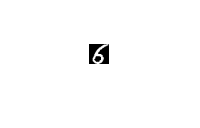

im=images(:,:,631);
imshow(im)

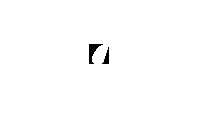

Dades=regionprops(im,'all');
conv=bwconvhull(im);
imshow(conv)

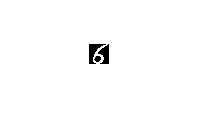

bw=im2bw(im);
imshow(bw)

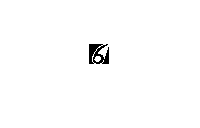

res=imsubtract(conv,bw);
imshow(res)

%imshow(Dades.ConvexImage)

T2 = T;
idx = fscchi2(T,'Var2917');
for i = 584:2916
    var = 'Var';
    r = strcat(var,int2str(idx(i)));
    T2 = removevars(T2,r);
end

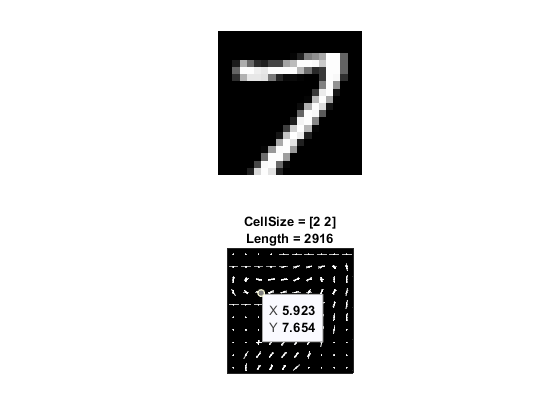

img = images(:,:,2);
% Extract HOG features and HOG visualization
[hog_2x2, vis2x2] = extractHOGFeatures(img,'CellSize',[2 2]);

% Show the original image
figure; 
subplot(2,2,1:2); imshow(img);

% Visualize the HOG features
subplot(2,1,2);  
plot(vis2x2); 
title({'CellSize = [2 2]'; ['Length = ' num2str(length(hog_2x2))]});